# Response threshold model

delta = [1, 6]; %the inherent increase in the stimulus for each task
alpha = [0.005, 0.005]; %the efficiency of the workers for each task

%num_workers =1200
num_workers = round(delta(1)/alpha(1)) + round(delta(2)/alpha(2));
num_tasks = 2;
num_steps = 2000;



worker_thresholds =  [100*(0.95+ 0.1*rand(num_workers,1)),100*(0.95+0.1*rand(num_workers,1))];

%worker_thresholds =  [400*(0.95+ 0.1*rand(round(num_workers/2),1)) , 100*(0.95+ 0.1*rand(round(num_workers/2),1))
%                     100*(0.95+ 0.1*rand(num_workers-round(num_workers/2),1)), 400*(0.95+ 0.1*rand(num_workers-round(num_workers/2),1))] 
 
%This is the final case where workers were split into groups with different
%thresholds

stimulus = 0*ones(1,num_tasks); %stimulus for each task starts at 0
perception_errs = -10 + 20*rand(num_workers, num_tasks); %Errors with which workers perceive stimulus

S = zeros(num_steps, num_tasks); %stimulus history
Task_performance = zeros(num_steps, num_tasks);
Worker_tasks = zeros(num_workers,num_steps);    

for steps = 1:num_steps
   A = [0 0];
    for a = 1:num_workers
        task_order = randperm(num_tasks); % so individuals motivated to do both tasks will choose one at random

        for p=1:num_tasks
            t = task_order(p); %Randomly ordering the tasks
            if compute_phi(stimulus(t), worker_thresholds(a,t), perception_errs(a,t)) == 1
                  A(t) = A(t) + 1; %Updates amount of workers dedicated to a certain task
                  Worker_tasks(a,steps)=t;
                break %ensures workers only perform one task
            end
        
        end
    end

    for i = 1:num_tasks
        stimulus(i) = stimulus(i) + delta(i) - alpha(i)*A(i); %Updates the stimulus over time
        stimulus(i) = max(stimulus(i), 0); %ensures that the stimulus does not fall below 0

    S(steps, i) = stimulus(i); %Updates the stimulus history to show variation in stimulus over time
    Task_performance(steps, i) = A(i); %Updates the variation in the amount of workers performing each task over time
    end
end


## Stimulus variation plot

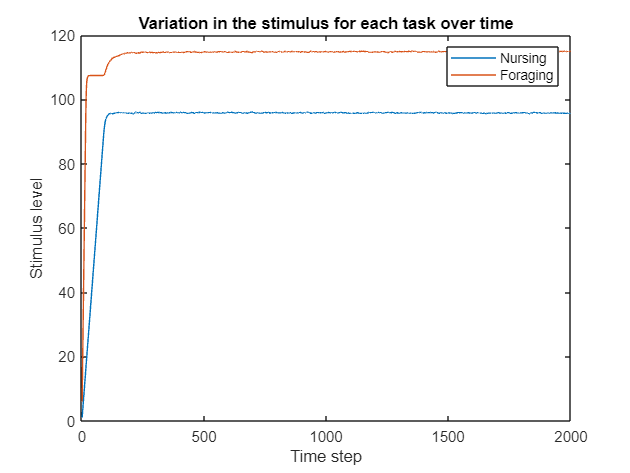

plot(S);
title('Variation in the stimulus for each task over time');
xlabel('Time step');
ylabel('Stimulus level');
legend('Nursing', 'Foraging');

## Amount of workers over time plot

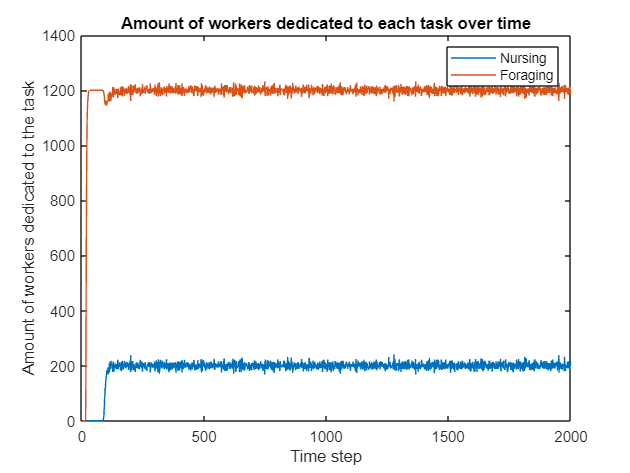

plot(Task_performance);
title('Amount of workers dedicated to each task over time');
xlabel('Time step');
ylabel('Amount of workers dedicated to the task');
legend('Nursing', 'Foraging');

## Calculation of division of labour

repetitions = zeros(num_steps,1);

for j = 2:num_steps
    for i=1:num_workers
        if Worker_tasks(i,j) ~= 0
           if Worker_tasks(i,j)==Worker_tasks(i,j-1)
                 repetitions(j)=repetitions(j)+1;
           end
        end
    end
end


A1 = Task_performance(:,1);
A2 = Task_performance(:,2);
AA = A1 + A2;
q = repetitions./AA;
p1 = A1./AA;
p2 = A2./AA;

D = [];
for i =1:length(q)
    if p1(i)==0 || p2(i)==0
        D(i) = NaN;
    else
        D(i) = q(i)./(p1(i).^2 + p2(i).^2) - 1;
    end
end

## Division of labour over time plot

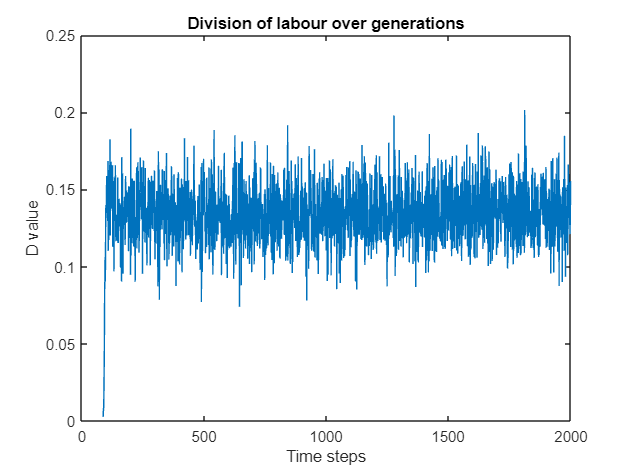

figure
plot(D)
title('Division of labour over generations')
xlabel('Time steps')
ylabel('D value')

function phi = compute_phi(Si, theta_i, epsilon_i)
    if Si + epsilon_i >= theta_i
        phi = 1;
    else
        phi = 0;
    end
end